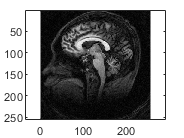

% Zero-Filling
clear

% 2D Clinical Image
load BE280Ahw1im.mat
I = Mimage;
imagesc(I)
colormap(gray(256))
axis equal

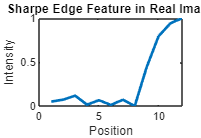

% Visualize Gibbs Ringing Artifact on specified region
data = I(68,42:53);
data_norm = (data - min(data))/(max(data)-min(data)); % normalize
f = abs(fftshift(fft(data)));
f_norm = (f-min(f))/(max(f)-min(f)); % normalize
figure; plot(data_norm,'LineWidth', 2)
xlabel('Position')
ylabel('Intensity')
title('Sharpe Edge Feature in Real Image')

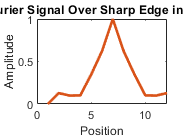

plot(f_norm, 'LineWidth', 2, 'color', "#D95319")
xlabel('Position')
ylabel('Amplitude')
title('Fourier Signal Over Sharp Edge in Image')

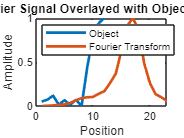

c = conv(data_norm, f_norm); % convolution of object and fourier
c_norm = (c - min(c))/(max(c) - min(c)); % normalize
figure; plot(data_norm,'LineWidth', 2)
hold on
plot(c_norm, 'LineWidth', 2)
hold off
xlabel('Position')
ylabel('Amplitude')
title('Fourier Signal Overlayed with Object Signal')
legend('Object', 'Fourier Transform', 'location', 'northwest')

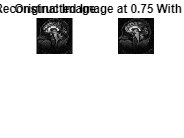

M = fftshift(fft2(I));
frac = 0.05:0.01:1; % initialize partial fourier fraction values
RMS = zeros(1, length(frac)); % root mean square error
W = hann(length(M)); % Hanning window with amplitude at 1
res = zeros(1, length(frac));
% Partial Fourier in Phase-Encoding Direction
for i = 1:length(frac)
    pM = M; % redefine for partial fourier transform
    pM(floor(size(I,1)*frac(i)):end, :) = 0; % zero-filling fraction of k-space (phase-encoded direction)
    full_spatial = max(max(M)); % full fourier transform spatial resolution
    partial_spatial = max(max(pM)); % partial fourier transform spatial resolution
    diff_spatial = abs(full_spatial - partial_spatial); % difference of spatial resolution
    res(i) = diff_spatial;
    imagesc(abs(pM),[200 1e6]);
    title('Partial Fourier in Phase Encoded Direction')
    colormap("gray")
    imagesc(abs(M),[200 1e6]);
    colormap("gray")
    N = ifft2(ifftshift(pM.*W));
    clf();
    subplot(2,2,1); imagesc(I); axis equal
    title('Original Image')
    axis('off')
    subplot(2,2,2); imagesc(abs(N)); axis equal
    axis('off')
    title('Reconstructed Image at 0.75 With Hanning (Phase)')
    colormap(gray(256))
    RMS(i) = norm(abs(N(:))-abs(I(:)))/(norm(abs(I(:)))); % root mean square
end

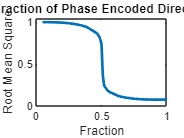


% Root Mean Square Plot
figure
plot(frac,RMS, 'LineWidth', 2)
ylim([0 1.05])
title('RMS for Each Fraction of Phase Encoded Direction With Hanning')
xlabel('Fraction')
ylabel('Root Mean Square')

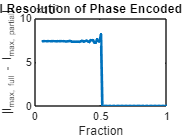



% Spatial Resolution Plot
figure
plot(frac,res, 'LineWidth', 2)
title('Spatial Resolution of Phase Encoded Direction')
xlabel('Fraction')
ylabel('|I_{max, full} - I_{max, partial}|')

% Zero-Filling
clear

% 2D Clinical Image
load BE280Ahw1im.mat
I = Mimage;
imagesc(I)
colormap(gray(256))
axis equal

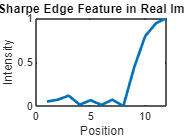

% Visualize Gibbs Ringing Artifact on specified region
data = I(68,42:53);
data_norm = (data - min(data))/(max(data)-min(data)); % normalize
f = abs(fftshift(fft(data)));
f_norm = (f-min(f))/(max(f)-min(f)); % normalize
figure; plot(data_norm,'LineWidth', 2)
xlabel('Position')
ylabel('Intensity')
title('Sharpe Edge Feature in Real Image')

plot(f_norm, 'LineWidth', 2, 'color', "#D95319")
xlabel('Position')
ylabel('Amplitude')
title('Fourier Signal Over Sharp Edge in Image')

c = conv(data_norm, f_norm); % convolution of object and fourier
c_norm = (c - min(c))/(max(c) - min(c)); % normalize
figure; plot(data_norm,'LineWidth', 2)
hold on
plot(c_norm, 'LineWidth', 2)
hold off
xlabel('Position')
ylabel('Amplitude')
title('Fourier Signal Overlayed with Object Signal')
legend('Object', 'Fourier Transform', 'location', 'northwest')

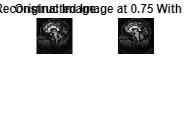

M = fftshift(fft2(I));
frac = 0.05:0.01:1; % initialize partial fourier fraction values
RMS = zeros(1, length(frac)); % root mean square error
W = hann(length(M)); % Hanning window with amplitude at 1
res = zeros(1, length(frac));
% Partial Fourier in Phase-Encoding Direction
for i = 1:length(frac)
    pM = M; % redefine for partial fourier transform
    pM(:, floor(size(I,1)*frac(i)):end) = 0; % zero-filling fraction of k-space (frequency-encoded direction)
    full_spatial = max(max(M)); % full fourier transform spatial resolution
    partial_spatial = max(max(pM)); % partial fourier transform spatial resolution
    diff_spatial = abs(full_spatial - partial_spatial); % difference of spatial resolution
    res(i) = diff_spatial;
    imagesc(abs(pM),[200 1e6]);
    title('Partial Fourier in Frequency Encoded Direction')
    colormap("gray")
    imagesc(abs(M),[200 1e6]);
    colormap("gray")
    N = ifft2(ifftshift(pM.*W));
    clf();
    subplot(2,2,1); imagesc(I); axis equal
    title('Original Image')
    axis('off')
    subplot(2,2,2); imagesc(abs(N)); axis equal
    axis('off')
    title('Reconstructed Image at 0.75 With Hanning (Frequency)')
    colormap(gray(256))
    RMS(i) = norm(abs(N(:))-abs(I(:)))/(norm(abs(I(:)))); % root mean square
end

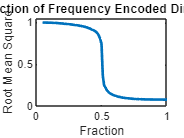


% Root Mean Square Plot
figure
plot(frac,RMS, 'LineWidth', 2)
ylim([0 1.05])
title('RMS for Each Fraction of Frequency Encoded Direction With Hanning')
xlabel('Fraction')
ylabel('Root Mean Square')

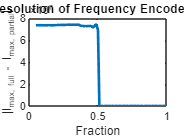



% Spatial Resolution Plot
figure
plot(frac,res, 'LineWidth', 2)
title('Spatial Resolution of Frequency Encoded Direction')
xlabel('Fraction')
ylabel('|I_{max, full} - I_{max, partial}|')

% Lower Resolution Comparison

% 2D Clinical Image
I = phantom(96);
imagesc(I)
colormap(gray(256))
axis equal
M = fftshift(fft2(I));
frac = 0.05:0.01:1;
RMS = zeros(1, length(frac));
W = hann(length(M)); % include figure for different hanning amplitudes
res = zeros(1, length(frac));
% Partial Fourier in Phase-Encoding Direction
for i = 1:length(frac)
    pM = M;
    pM(floor(size(I,1)*frac(i)):end, :) = 0;
    full_spatial = max(max(M));
    partial_spatial = max(max(pM));
    diff_spatial = abs(full_spatial - partial_spatial);
    res(i) = diff_spatial;
    imagesc(abs(pM),[200 1e6]);
    title('Partial Fourier in Phase Encoded Direction')
    colormap("gray")
    imagesc(abs(M),[200 1e6]);
    colormap("gray")
    N = ifft2(ifftshift(pM));
    clf();
    subplot(2,2,1); imagesc(I); axis equal
    title('Original Image')
    axis('off')
    subplot(2,2,2); imagesc(abs(N)); axis equal
    axis('off')
    title('Reconstructed Image at 0.75 With Hanning (Phase)')
    colormap(gray(256))
    RMS(i) = norm(abs(N(:))-abs(I(:)))/(norm(abs(I(:))));
end